This script serves to perform the required calibration needed to convert the radar permittivity to pseudoRAW values that allow us to use the TEROS 12 calibration process for various soil types.

c=299792458;                    % Speed of light (m/s)
resolution = 0.003790984152165; % Range resolution (m)

runName = {};
radarPermittivity = [];
expectedRAW = [];

`Ground truth data stored in `

[`https://docs.google.com/spreadsheets/d/1K78VeHgP5uEu7g3LeU7YA1ABJxbuOkrdziNVeoTXbkk/edit?usp=sharing`](https://docs.google.com/spreadsheets/d/1K78VeHgP5uEu7g3LeU7YA1ABJxbuOkrdziNVeoTXbkk/edit?usp=sharing)

`Starting with the dry run`

databaseName = '/data/chi-run-1/DryRun';
tag1Hz = 64;
tag2Hz = 105;

peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, false);

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(3.28e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity(end+1) = radar_perm;
expectedRAW(end+1) = TEROS_raw;

`Second run`

databaseName = '/data/chi-run-2';
tag1Hz = 64;
tag2Hz = 105;

peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, false);

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(15.45e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity(end+1) = radar_perm;
expectedRAW(end+1) = TEROS_raw;

`Third run (something is off about this)`

% databaseName = '/data/chi-run-3';
% tag1Hz = 64;
% tag2Hz = 105;
% 
% peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, true);
% 
% distance = 2/39.37;                         % Distance between tags (m)
% t = ((peakDifference + ...
%     distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
% radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity
% 
% TEROS_raw = 2031.86;                        % Taken from TEROS sensor readings
% 
% % Appending data to results table
% runName(end+1) = {databaseName};
% radarPermittivity(end+1) = radar_perm;
% expectedRAW(end+1) = TEROS_raw;


Fourth run

databaseName = '/data/chi-run-4';
tag1Hz = 64;
tag2Hz = 105;

peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, false);

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(21.58e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity(end+1) = radar_perm;
expectedRAW(end+1) = TEROS_raw;

Fifth run

databaseName = '/data/chi-run-5';
tag1Hz = 64;
tag2Hz = 105;

peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, false);

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(21.90e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity(end+1) = radar_perm;
expectedRAW(end+1) = TEROS_raw;

Sixth run

databaseName = '/data/chi-run-6';
tag1Hz = 64;
tag2Hz = 105;

peakDifference = RunDualTagDataset2(databaseName, tag1Hz, tag2Hz, false);

distance = 2/39.37;                         % Distance between tags (m)
t = ((peakDifference + ...
    distance/resolution) * resolution) / c; % Time of Flight (ToF) from on tag to the other (s)
radar_perm = ((c*t)/distance).^2;           % ToF converted to permittivity

TEROS_raw = CalibrateVWC2RAW(25.12e-2);      % TODO: document

% Appending data to results table
runName(end+1) = {databaseName};
radarPermittivity(end+1) = radar_perm;
expectedRAW(end+1) = TEROS_raw;

Final stuff.

% Final table of results
results = table(transpose(runName), transpose(radarPermittivity), transpose(expectedRAW), ...
    'VariableNames', {'Run Name', 'Radar Permitivvity', 'Expected Raw'});

disp(results)

             Run Name             Radar Permitivvity    Expected Raw
    __________________________    __________________    ____________

    {'/data/chi-run-1/DryRun'}          100.59               1946   
    {'/data/chi-run-2'       }          103.61             2143.4   
    {'/data/chi-run-4'       }          112.93             2292.2   
    {'/data/chi-run-5'       }          171.33             2301.2   
    {'/data/chi-run-6'       }          177.24             2402.3   



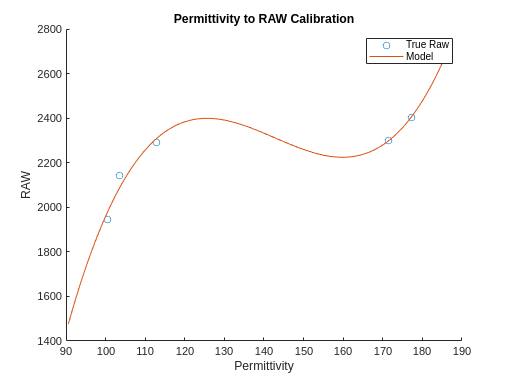


permittivity2raw = polyfit(radarPermittivity, expectedRAW, 3);

figure
scatter(radarPermittivity, expectedRAW)
hold on
radarPermittivityPoints = linspace(min(radarPermittivity) - 10, max(radarPermittivity) + 10, 100);
plot(radarPermittivityPoints, polyval(permittivity2raw, radarPermittivityPoints))
legend(["True Raw", "Model"])
xlabel("Permittivity")
ylabel("RAW")
title("Permittivity to RAW Calibration")